# Specify the Orientation of Text in a Table Entry in a Presentation

To specify the orientation of the text in a table entry in a presentation, add an `mlreportgen.ppt.TextOrientation` object to the S`tyle` property of the `mlreportgen.ppt.TableEntry` object that represents the table entry. This example generates a table with vertically oriented text in the first row.

Create a presentation.

import mlreportgen.ppt.*
ppt = Presentation("myTextOrientation.pptx");
open(ppt);

Add a slide to the presentation.

slide = add(ppt,"Title and Table");

Create a table.

t = Table({'Entry 11', 'Entry 12'; 'Entry 21', 'Entry 22'});
t.Height = '2in';
t.Width = '2in';
t.StyleName = "Medium style 2 - Accent 1";
t.Style = [t.Style {VAlign("middleCentered")}];

Specify the vertical text orientation for the entries in the first row.

tr1te1 = t.entry(1,1);
tr1te1.Style = [ tr1te1.Style {TextOrientation("down")} ];
tr1te2 = t.entry(1,2);
tr1te2.Style = [ tr1te2.Style {TextOrientation("down")} ];

Add a title and the table to the slide.

replace(slide,"Title","Row One Text Has Vertical Orientation");
replace(slide,"Table",t);

Close and view the presentation.

close(ppt);
rptview(ppt);

Here is the table in the generated presentation:

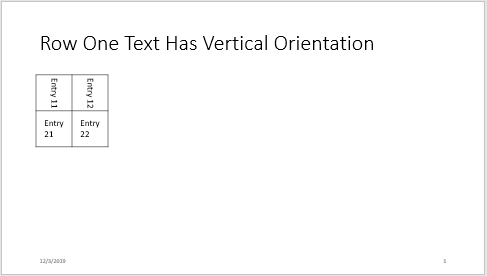

*Copyright 2019 The MathWorks, Inc.*